clc
clear

step = 1; % 5

Kt = 0.011;
Km = 327*10^-6;
M = 1.513;
Ixx = 0.0185;
Iyy = 0.0201;
Izz = 0.0286;
g = 9.82;
lroll = 0.175;
lpitch = 0.175;
omega_m = M*g/(4*Kt);

Ts = 1/800;

n = 12; % number of states
m = 4; % number of inputs
p = 12; % number of outputs

## Motor Mixing Algorithm

MMA = [1/4 -1/4 -1/4 -1/4 ; 1/4 1/4 1/4 -1/4 ; 1/4 1/4 -1/4 1/4 ; 1/4 -1/4 1/4 1/4];
%MMA_inv = inv(MMA);
MMA_inv = [1 1 1 1 ; -1 1 1 -1 ; -1 1 -1 1 ; -1 -1 1 1];

## Tuning parameters

Hp = 10; % prediction horizon
Hu = 1; % control horizon
Q = zeros(Hp*p); % error weight

% add error weight for full prediction horizon
for k=1:Hp
    Q((k-1)*p+1,(k-1)*p+1) = 50; % velocity x % 100 % 50
    Q((k-1)*p+2,(k-1)*p+2) = 50; % velocity y
    Q((k-1)*p+3,(k-1)*p+3) = 50; % velocity z
    Q((k-1)*p+4,(k-1)*p+4) = 1; % angular velocity roll % 25 % 1
    Q((k-1)*p+5,(k-1)*p+5) = 1; % angular velocity pitch
    Q((k-1)*p+6,(k-1)*p+6) = 5000; % angular velocity yaw
    Q((k-1)*p+7,(k-1)*p+7) = 1250; % x % 2500 % 1250, 1300 også godt
    Q((k-1)*p+8,(k-1)*p+8) = 1250; % y
    Q((k-1)*p+9,(k-1)*p+9) = 1250; % z
    Q((k-1)*p+10,(k-1)*p+10) = 125; % roll % 500 % 100
    Q((k-1)*p+11,(k-1)*p+11) = 125; % pitch
    Q((k-1)*p+12,(k-1)*p+12) = 5000; % yaw
end

R = 0.01*eye(Hu*m); % change in actuation weight

rho = 5000000; % slack variable weight

#### Constraints

W = [0 0 0 0];

Fscript = [-1/omega_m 0 0 0 ; 
            1/(1059-omega_m) 0 0 0 ;
            0 -1/omega_m 0 0 ; 
            0 1/(1059-omega_m) 0 0 ;
            0 0 -1/omega_m 0 ; 
            0 0 1/(1059-omega_m) 0 ;
            0 0 0 -1/omega_m ; 
            0 0 0 1/(1059-omega_m)];

Gamma = [-1/10 0 0 0 0 0 0 0 0 0 0 0 ;
            1/10 0 0 0 0 0 0 0 0 0 0 0 ;
            0 -1/10 0 0 0 0 0 0 0 0 0 0 ;
            0 1/10 0 0 0 0 0 0 0 0 0 0 ;
            0 0 -1/10 0 0 0 0 0 0 0 0 0 ;
            0 0 1/10 0 0 0 0 0 0 0 0 0 ;
            0 0 0 0 0 0 0 0 0 -1/0.35 0 0 ;
            0 0 0 0 0 0 0 0 0 1/0.35 0 0 ;
            0 0 0 0 0 0 0 0 0 0 -1/0.35 0 ;
            0 0 0 0 0 0 0 0 0 0 1/0.35 0 ;
            0 0 0 0 0 0 0 0 0 0 0 -1/0.05 ;
            0 0 0 0 0 0 0 0 0 0 0 1/0.05];

% concatenate constraints over full horizon
%Fscript = [];
%Gamma = [];
%W = [];
temp = Fscript;
for k=2:Hu
    Fscript = blkdiag(Fscript, temp);
end
fsmall = -1*ones(height(Fscript),1);

temp = Gamma;
for k=2:Hp
    Gamma = blkdiag(Gamma, temp);
end
gsmall = -1*ones(height(Gamma),1);

## Linear model and lifting

A = [zeros(6,6)  [0 0 0 0 g 0; 0 0 0 -g 0 0 ; zeros(4,6)];
    eye(6) zeros(6,6)];
B = [zeros(4,2) [Kt/M -(lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/M (lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) -(Km)/(Izz); 
    Kt/M (lroll*Kt)/(Ixx) -(lpitch*Kt)/(Iyy) (Km)/(Izz); 
    Kt/M -(lroll*Kt)/(Ixx) (lpitch*Kt)/(Iyy) (Km)/(Izz)] zeros(4,6)].';
C = eye(p,n);
D = zeros(p,m);

SSModel = ss(A,B,C,D); % discretise model
opt = c2dOptions('Method','tustin');
sys = c2d(SSModel,1/100,opt);

% Lift matrices
[ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(sys.A, sys.B, sys.C, Hp, Hu);

Condition of:
 Psi: 1.782631
 Upsilon: 14.313564 
 Theta: 14.313564

xTest = 1; % temp variables to block for loop from running all the time
yTest = 1;
zTest = 1;

simSeconds = 10; % simulate for how many seconds
simTime = simSeconds/Ts;
t = linspace(0,simSeconds,simTime);

x = zeros(n,simTime);
u = zeros(m,simTime);
du = zeros(m,simTime);

Tau = zeros(n,1); % reference tau

% position references
Tau(7,1) = step;
Tau(8,1) = step;
Tau(9,1) = 1;

% Concatenate references over full horizon
temp = Tau;
for k=2:Hp
    Tau = [Tau ; temp];
end

prog = waitbar(0, 'Starting');
for i=2:simTime
    % Calculate the Plant
    % plant sampled at 800 hz
    x(:,i) = NonLinear_Simulation(x(:,i-1),(omega_m + u(:,i-1)),Ts);
    
    if(mod(Ts*i,1/100) == 0)
        yalmip('clear')
        duopt = sdpvar(Hu*m,1);
        slack = sdpvar(height(Gamma),1); % slacks only added on states

        % create constraints for yalmip
        constraint = [];
        % constraints for input
        for k=1:height(Fscript)
            constraint = [constraint ; Fscript(k,:)*duopt <= -Fscript(k,1:m)*u(:,i-1)-fsmall(k)];
        end
        % constraints for states
        for k=1:height(Gamma)
            constraint = [constraint ; Gamma(k,:)*Theta*duopt <= -Gamma(k,:)*(Psi*x(:,i)+Upsilon*u(:,i-1))-gsmall(k)+slack(k)];
        end
        constraint = [constraint ; slack >= 0];
    
        Epsilon = Tau - Psi * x(:,i) - Upsilon * u(:,i-1);
        G = 2 * Theta.' * Q * Epsilon;
        H = Theta.' * Q * Theta + R;
        objective = (duopt.' * H * duopt - duopt.' * G + rho*norm(slack,2)^2);
    
        ops = sdpsettings('solver','ipopt');
        ops.verbose = 0; % makes yalmip quiet
        optimize(constraint,objective, ops);
    
        du(:,i) = duopt(1:4,1);
    
        % change inputs from inertial frame to body frame
        omega_IB = MMA_inv*du(:,i);
        omega_IB(2:4) = R_IB(x(10,i), x(11,i), x(12,i))*omega_IB(2:4);
        du(:,i) = MMA*omega_IB;
    end

    u(:,i) = u(:,i-1) + du(:,i);

    waitbar(i/simTime, prog, sprintf('Progress: %d %%', floor(i/simTime*100)));
end
close(prog)

save("Data\MPCStepResponseTest", "t","x",'u');

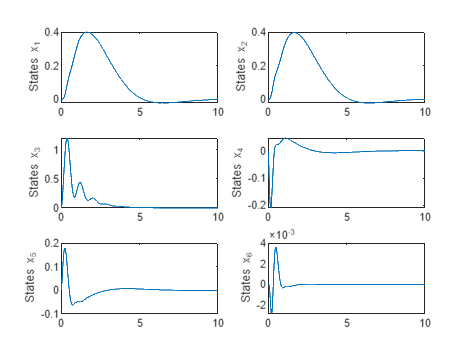

figure(1);
subplot(3,2,1)
plot(t, x(1,:));
ylabel("States x_1")
subplot(3,2,2)
plot(t, x(2,:));
ylabel("States x_2")
subplot(3,2,3)
plot(t, x(3,:));
ylabel("States x_3")
subplot(3,2,4)
plot(t, x(4,:));
ylabel("States x_4")
subplot(3,2,5)
plot(t, x(5,:));
ylabel("States x_5")
subplot(3,2,6)
plot(t, x(6,:));
ylabel("States x_6")

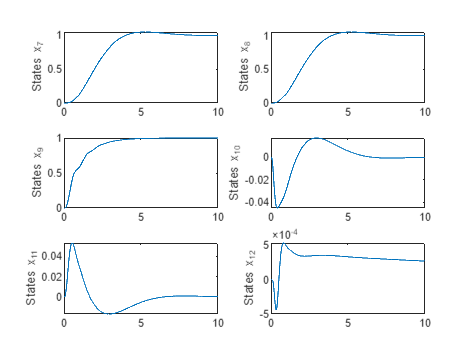

figure(2);
subplot(3,2,1)
plot(t, x(7,:));
ylabel("States x_7")
subplot(3,2,2)
plot(t, x(8,:));
ylabel("States x_8")
subplot(3,2,3)
plot(t, x(9,:));
ylabel("States x_9")
subplot(3,2,4)
plot(t, x(10,:));
ylabel("States x_10")
subplot(3,2,5)
plot(t, x(11,:));
ylabel("States x_11")
subplot(3,2,6)
plot(t, x(12,:));
ylabel("States x_12")

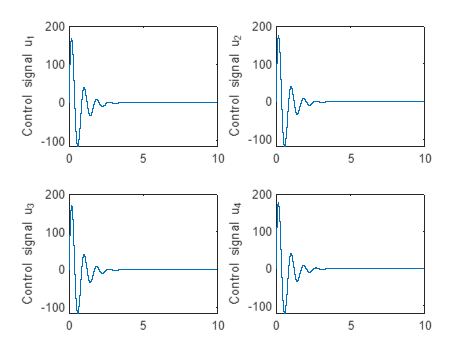

figure(3)
subplot(2,2,1)
stairs(t, u(1,:));
ylabel("Control signal u_1")
subplot(2,2,2)
stairs(t, u(2,:));
ylabel("Control signal u_2")
subplot(2,2,3)
stairs(t, u(3,:));
ylabel("Control signal u_3")
subplot(2,2,4)
stairs(t, u(4,:));
ylabel("Control signal u_4")

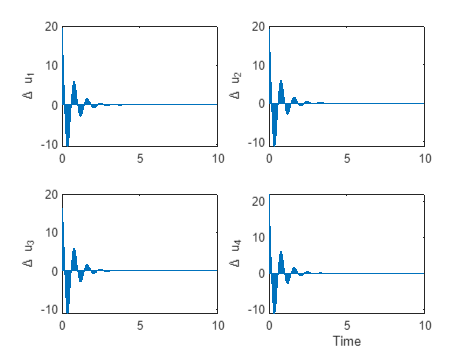

figure(4)
subplot(2,2,1)
stairs(t, du(1,:));
ylabel("\Delta u_1")
subplot(2,2,2)
stairs(t, du(2,:));
ylabel("\Delta u_2")
subplot(2,2,3)
stairs(t, du(3,:));
ylabel("\Delta u_3")
subplot(2,2,4)
stairs(t, du(4,:));
ylabel("\Delta u_4")
xlabel("Time")

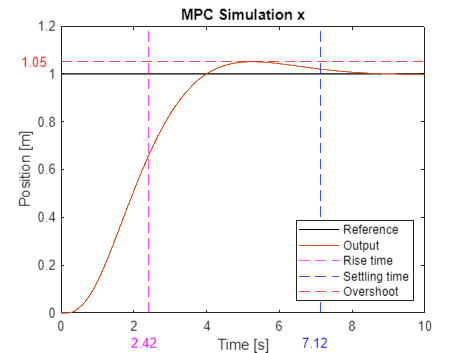

figure(5)
plot(t,ones(1,8000),'black',t, x(7,:))
title('MPC Simulation x')
xlabel('Time [s]');
ylabel('Position [m]');
xline((2647-714)*Ts,'--',Color='[1,0,1]')
xline(5697*Ts,'--',Color='b')
yline(max(x(7,:)),'--',Color='[1,0,0]')
text(-1.1, max(x(7,:)), sprintf('%.2f', max(x(7,:))),Color='[1,0,0]');
text((2647-714)*Ts-0.5, -0.125, sprintf('%.2f', (2647-714)*Ts),Color='[1,0,1]');
text(5697*Ts-0.5, -0.125, sprintf('%.2f', 5697*Ts),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot','Location','southeast')
saveas(gcf,'images/MPC_X','epsc')

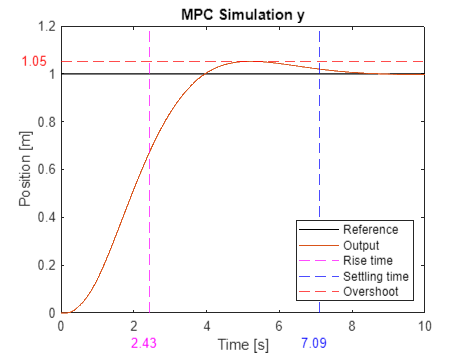

figure(6)
plot(t,ones(1,8000),'black',t, x(8,:))
title('MPC Simulation y')
xlabel('Time [s]');
ylabel('Position [m]');
xline((2627-682)*Ts,'--',Color='[1,0,1]')
xline(5673*Ts,'--',Color='b')
yline(max(x(8,:)),'--',Color='[1,0,0]')
text(-1.1, max(x(8,:)), sprintf('%.2f', max(x(8,:))),Color='[1,0,0]');
text((2627-682)*Ts-0.5, -0.125, sprintf('%.2f', (2627-682)*Ts),Color='[1,0,1]');
text(5673*Ts-0.5, -0.125, sprintf('%.2f', 5673*Ts),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot','Location','southeast')
saveas(gcf,'images/MPC_Y','epsc')

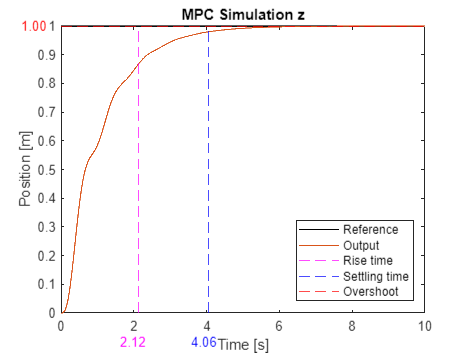

figure(7)
plot(t,ones(1,8000),'black',t, x(9,:))
title('MPC Simulation z')
xlabel('Time [s]');
ylabel('Position [m]');
xline((1907-208)*Ts,'--',Color='[1,0,1]')
xline(3247*Ts,'--',Color='b')
yline(max(x(9,:)),'--',Color='[1,0,0]')
text(-1.1, max(x(9,:)), sprintf('%.2f', max(x(9,:))),Color='[1,0,0]');
text((1907-208)*Ts-0.5, -0.1, sprintf('%.2f', (1907-208)*Ts),Color='[1,0,1]');
text(3247*Ts-0.5, -0.1, sprintf('%.2f', 3247*Ts),Color='b');
legend('Reference','Output','Rise time','Settling time','Overshoot','Location','southeast')
saveas(gcf,'images/MPC_Z','epsc')

function [ALift, BuLift, BduLift, Psi, Upsilon, Theta] = MPCLift(A, B, C, Hp, Hu)
    n = length(A);
    p = size(B,2);
    ALift = zeros(Hp*n,n);
    BuLift = zeros(Hp*n,p);
    BduLift = zeros(Hp*n,Hu*p);
    for i=1:Hp
        ALift((i-1)*n+1:i*n,:) = A^i;

        Asum = 0;
        for j=2:i
            Asum = Asum + ALift((j-2)*n+1:(j-1)*n,:);
        end
        % We add B, since the above loop doesnt go A^0*B = 1*B = B
        BuLift((i-1)*n+1:i*n,:) = Asum * B + B;
    end

    for i=1:Hu
        BduLift((i-1)*n+1:end,(i-1)*p+1:i*p) = BuLift(1:(Hp-(i-1))*n,:);
    end

    C_vec = kron(eye(Hp), C);
    cal_C = blkdiag(C_vec);
    
    Psi = cal_C * ALift;
    Upsilon = cal_C * BuLift;
    Theta = cal_C * BduLift;
    fprintf("Condition of:\n Psi: %f\n Upsilon: %f \n Theta: %f",cond(Psi),cond(Upsilon),cond(Theta))
end

function [R_IB] = R_IB(roll_I, pitch_I, yaw_I)
    R_IB = [cos(pitch_I)*cos(yaw_I) cos(pitch_I)*sin(yaw_I) -sin(pitch_I) ; cos(yaw_I)*sin(pitch_I)*sin(roll_I)-cos(roll_I)*sin(yaw_I) cos(yaw_I)*cos(roll_I)+sin(pitch_I)*sin(yaw_I)*sin(roll_I) cos(pitch_I)*sin(roll_I) ; sin(yaw_I)*sin(roll_I)+cos(yaw_I)*cos(roll_I)*sin(pitch_I) cos(roll_I)*sin(pitch_I)*sin(yaw_I)-cos(yaw_I)*sin(roll_I) cos(pitch_I)*cos(roll_I)];
end
